# Introduction to Matlab functionality for System Modelling and Analysis

# About this document

This document is intended to provide a brief introduction and a concise reference to get you going with Matlab for modelling and simulation of dynamic systems.

**** State-space models are NOT IN THE SCOPE  of Mechatronics-3 course, but are included for completeness. You may skip over those sections. ****

This document is a "live" Matlab file (.mlx), meaning that executable `Matlab code` can be mixed with formatted text, LaTex equations and graphics. (In contrast, Matlab .m files can contain only `executable code`  and `comments,` which start with a `%` sign in each line)

- Grey boxes contain `executable code`

- Chunks of text or code are grouped in `cells`, separated by `section breaks`

You can run:

- All code in the document:    press **Run** button

- Current cell (where cursor is):    press **Run Section **(NB: previously run code may initialise certain variables)

- Step through cells in a sequence:    press **Run and Advance**

Code output:

- may be viewed either in a single or double pane configuration (**View** tab)

- Figures may be opened in a separate window

# 1.    System Modeling

The first step in the control design process is to develop appropriate mathematical models of the system to be controlled. These models may be derived either from physical laws or experimental data. In this section, we introduce the state-space and transfer function representations of dynamic systems. We then review some basic approaches to modeling mechanical and electrical systems and show how to generate these models in MATLAB for further analysis. 

Key MATLAB commands used in this tutorial are: [`ss`](http://www.mathworks.com/help/toolbox/control/ref/ss.html) ,  [`tf`](http://www.mathworks.com/help/toolbox/control/ref/tf.html)

## Dynamic Systems

**Dynamic systems** are systems that change or evolve in time according to a fixed rule. For many physical systems, this rule can be stated as a set of first-order differential equations:


$$ 
\dot{\mathbf{x}} = \frac{d\mathbf{x}}{dt} = \mathbf{f}\left( \mathbf{x}(t), \mathbf{u}(t), t \right)
$$


In the above equation, $\mathbf{x}(t)$ is the **state vector**, a set of variables representing the configuration of the system at time $t$. For instance, in a simple mechanical mass-spring-damper system, the two state variables could be the position and velocity of the mass. $\mathbf{u}(t)$ is the vector of external inputs to the system at time $t$, and $\mathbf{f}$ is a (possibly nonlinear) function producing the time derivative (rate of change) of the state vector, $d\mathbf{x}/dt$, for a particular instant of time.

The state at any future time, $\mathbf{x}(t_1)$, may be determined exactly given knowledge of the initial state, $\mathbf{x}(t_0)$, and the time history of the inputs, $\mathbf{u}(t)$, between $t_0$ and $t_1$ by integrating Equation (1). Though the state variables themselves are not unique, there is a minimum number of state variables, $n$, required in order to capture the "state" of a given system and to be able to predict the system's future behavior (solve the state equations).  $n$ is referred to as the **system order** and determines the dimensionality of the **state-space**. The system order usually corresponds to the number of independent energy storage elements in the system.

The relationship given in Equation (1) is very general and can be used to describe a wide variety of different systems; unfortunately, it may be very difficult to analyze. There are two common simplifications which make the problem more tractable. First, if the function $\mathbf{f}$ does not depend explicitly on time, i.e. $\dot{\mathbf{x}} = \mathbf{f}(\mathbf{x},\mathbf{u})$, then the system is said to be **time invariant**. This is often a very reasonable assumption because the underlying physical laws themselves do not typically depend on time. For time-invariant systems, the parameters or coefficients of the function $\mathbf{f}$ are constant. The state variables, $\mathbf{x}(t)$, and control inputs, $\mathbf{u}(t)$, however, may still be time dependent. 

The second common assumption concerns the linearity of the system. In reality, nearly every physical system is nonlinear. In other words,  $\mathbf{f}$ is typically some complicated function of the state and inputs. These nonlinearities arise in many different ways, one of the most common in control systems being "saturation" in which an element of the system reaches a hard physical limit to its operation. Fortunately, over a sufficiently small operating range (think tangent line near a curve), the dynamics of most systems are approximately **linear**. In this case, the system of first-order differential equations can be represented as a matrix equation, that is, $\dot{\mathbf{x}} = A\mathbf{x} + B\mathbf{u}$. 

Until the advent of digital computers (and to a large extent thereafter), it was only practical to analyze **linear time-invariant (LTI)** systems. Consequently, most of the results of control theory are based on these assumptions. Fortunately, as we shall see, these results have proven to be remarkably effective and many significant engineering challenges have been solved using LTI techniques. In fact, the true power of feedback control systems are that they work (are **robust**) in the presence of the unavoidable modeling uncertainty.

## State-Space Representation

For continuous linear time-invariant (LTI) systems, the standard state-space representation is given below:


$$ 
\dot{\mathbf{x}} = A\mathbf{x} + B\mathbf{u}
$$



$$ 
\mathbf{y} = C\mathbf{x} + D\mathbf{u}
$$


where $\mathbf{x}$ is the vector of state variables (nx1), $\dot{\mathbf{x}}$ is the time derivative of the state vector (nx1), $\mathbf{u}$ is the input or control vector (px1), $\mathbf{y}$ is the output vector (qx1), $A$ is the system matrix (nxn),  $B$ is the input matrix (nxp),  $C$ is the output matrix (qxn), and $D$ is the feedforward matrix (qxp). 

%	
% The output equation, Equation (3), is necessary because often there are state 
% variables which are not directly observed or are otherwise not of
% interest.  The output matrix, $C$, is used to specify which
% state variables (or combinations thereof) are available for use by the 
% controller. Also, it is often the case that the outputs do not directly
% depend on the inputs (only through the state variables), in which case 
% $D$ is the zero matrix.
%
% The state-space representation, also referred to as the time-domain
% representation, can easily handle *multi-input/multi-output (MIMO)* systems, 
% systems with non-zero initial conditions, and nonlinear systems via Equation (1). 
% Consequently, the state-space representation is used extensively in 
% "modern" control theory. 
%

## Transfer Function Representation

LTI systems have the extremely important property that if the input to the system is sinusoidal, then the output will also be sinusoidal with the same frequency as the input, but with possibly different magnitude and phase. These magnitude and phase differences are a function of frequency and capture what is known as the **frequency response** of the system.

Using the **Laplace transform**, it is possible to convert a system's time-domain representation into a frequency-domain input/output representation, known as the **transfer function**. In so doing, it also transforms the governing differential equation into an algebraic equation which is often easier to analyze.

The Laplace transform of a time domain function, $f(t)$, is defined below:


$$
F(s) = \mathcal{L}\{f(t)\} = \int_0^\infty e^{-st}f(t)dt
$$


where the parameter $s=\sigma+j\omega$ is a complex frequency variable. It is very rare in practice that you will have to directly evaluate a Laplace transform (though you should certainly know how to). It is much more common to look up the transform of a time function in a table such as the one found here: [Laplace Transform Table](http://en.wikipedia.org/wiki/Laplace_transform#Table_of_selected_Laplace_transforms)

The Laplace transform of the nth derivative of a function is particularly important:


$$
\mathcal{L}\left\{ \frac{d^nf}{dt^n} \right\} = s^n F(s)- s^{n-1} f(0) - s^{n-2} \dot{f}(0) - ... - f^{(n-1)}(0)
$$


Frequency-domain methods are most often used for analyzing LTI **single-input/single-output (SISO)** systems, e.g. those governed by a constant coefficient differential equation, as shown below:


$$
a_n \frac{d^ny}{dt^n} + ... + a_1 \frac{dy}{dt} + a_0 y(t) = b_m \frac{d^mu}{dt^m} + ... + b_1 \frac{du}{dt} + b_0 u(t)
$$


The Laplace transform of this equation is given below:


$$
a_n s^n Y(s) + ... + a_1 sY(s)+ a_0 Y(s) = b_m s^m U(s) + ... + b_1 sU(s)+ b_0 U(s)
$$


where $Y(s)$ and $U(s)$ are the Laplace Transforms of $y(t)$ and $u(t)$, respectively. Note that when finding transfer functions, we always assume that the each of the initial conditions, $y(0)$, $\dot{y}(0)$, $u(0)$, etc. is zero. The transfer function from input $U(s)$ to output $Y(s)$ is, therefore:


$$
G(s) = \frac{Y(s)}{U(s)} = \frac{b_m s^m + b_{m-1} s^{m-1} + ... + b_1 s + b_0}{a_n s^n + a_{n-1} s^{n-1} + ... + a_1 s + a_0}
$$


It is useful to factor the numerator and denominator of the transfer function into what is termed **zero-pole-gain** form:


$$
G(s) = \frac{N(s)}{D(s)} = K \frac{(s-z_1)(s-z_2)...(s-z_{m-1})(s-z_m)}{(s-p_1)(s-p_2)...(s-p_{n-1})(s-p_n)}
$$


The **zeros** of the transfer function, $z_1,\ldots,z_m$, are the roots of the numerator polynomial, i.e. the values of $s$ such that $N(s)=0$. The **poles** of the transfer function, $p_1, \ldots,p_n$, are the roots of the denominator polynomial, i.e. the values of $s$ such that $D(s)=0$. Both the zeros and poles may be complex valued (have both real and imaginary parts). The system **Gain** is $K = b_m/a_n$.

Note that we can also determine the transfer function directly from the state-space representation as follows:


$$
G(s) = \frac{Y(s)}{U(s)} = C(s\mathbf{I}-A)^{-1}B+D
$$


## Mechanical Systems

Newton's laws of motion form the basis for analyzing mechanical systems.  **Newton’s second law**, Equation (11), states that the sum of the forces acting on a body equals the product of its mass and acceleration. **Newton's third law**, for our purposes, states that if two bodies are in contact, then they experience the same magnitude contact force, just acting in opposite directions.


$$
\Sigma \mathbf{F} = m \mathbf{a} = m \frac{d^2 \mathbf{x}}{dt^2}
$$


When applying this equation, it is best to construct a **free-body diagram (FBD)** of the sysetm showing all of the applied forces.

## Example: Mass-Spring-Damper System

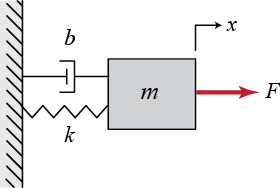

The free-body diagram for this system is shown below. The spring force is proportional to the displacement of the mass, $x$, and the viscous damping force is proportional to the velocity of the mass, $v=\dot{x}$. Both forces oppose the motion of the mass and are, therefore, shown in the negative  $x$-direction. Note also that $x=0$ corresponds to the position of the mass when the spring is unstretched. 

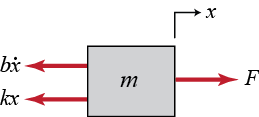

Now we proceed by summing the forces and applying Newton’s second law, Equation (11), in each direction. In this case, there are no forces acting in the $y$-direction; however, in the $x$-direction we have:


$$
\Sigma F_x = F(t) - b \dot{x} - k x = m \ddot{x}
$$


This equation, known as the **governing equation**, completely characterizes the dynamic state of the system. Later, we will see how to use this to calculate the response of the system to any external input, $F(t)$, as well as to analyze system properties such as stability and performance. 

To determine the state-space representation of the mass-spring-damper system, we must reduce the second-order governing equation to a set of two first-order differential equations. To this end, we choose the position and velocity as our state variables. 


$$
\mathbf{x} = \left[ \begin{array}{c} x \\ \dot{x} \end{array}\right]
$$


The position variable captures the potential energy stored in the spring, while the velocity variable captures the kinetic energy stored by the mass. The damper only dissipates energy, it doesn't store energy. Often when choosing state variables it is helpful to consider what variables capture the energy stored in the system. 

The state equation in this case is:


$$
\mathbf{\dot{x}} = \left[ \begin{array}{c} \dot{x} \\ \ddot{x} \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ -\frac{k}{m}  & -\frac{b}{m} \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right] + \left[ \begin{array}{c} 0 \\ \frac{1}{m} \end{array} \right] F(t)
$$


If, for instance, we are interested in controlling the position of the mass, then the output equation is:


$$
y = \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \left[ \begin{array}{c} x \\ \dot{x} \end{array} \right]
$$


## Entering State-Space Models into MATLAB

Now we will demonstrate how to enter the equations derived above into an `m-file` for MATLAB. Let's assign the following numerical values to each of the variables.

Create a new `m-file` and enter the following commands.

m = 1;
k = 1;
b = 0.2;
F = 1;

A = [0 1; -k/m -b/m];
B = [0 1/m]';
C = [1 0];
D = [0];


sys =
 
  A = 
         x1    x2
   x1     0     1
   x2    -1  -0.2
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys = ss(A,B,C,D)

The Laplace transform for this system assuming zero initial conditions is


$$
m s^2 X(s) + b s X(s) + k X(s) = F(s)
$$


and, therefore, the transfer function from force input to displacement output is


$$
\frac{X(s)}{F(s)} = \frac{1}{m s^2 + b s + k}
$$


## Entering Transfer Function Models into MATLAB

Now we will demonstrate how to create the transfer function model derived above within MATLAB. Enter the following commands into the `m-file` in which you defined the system parameters.

s = tf('s');

sys =
 
         1
  ---------------
  s^2 + 0.2 s + 1
 
Continuous-time transfer function.



sys = 1/(m*s^2+b*s+k)

Note that we have used the symbolic `s` variable here to define our transfer function model. We recommend using this method most of the time; however, in some circumstances, for instance in older versions of MATLAB or when interfacing with SIMULINK, you may need to define the transfer function model using the numerator and denominator polynomial coefficients directly. In these cases, use the following commands:

num = [1];
den = [m b k];

sys =
 
         1
  ---------------
  s^2 + 0.2 s + 1
 
Continuous-time transfer function.



sys = tf(num,den)

## Electrical Systems

Like Newton’s laws for mechanical systems, Kirchoff’s circuit laws are fundamental analytical tools for modeling electrical systems.  **Kirchoff’s current law (KCL)** states that the sum of the electrical currents entering a node in a circuit must equal the sum of electrical currents exiting the node. **Kirchoff’s voltage law (KVL)** states that the sum of voltage differences around any closed loop in a circuit is zero. When applying KVL, the source voltages are typically taken as positive and the load voltages are taken as negative.

## Example: RLC Circuit

We will now consider a simple series combination of three passive electrical elements: a resistor, an inductor, and a capacitor, known as an **RLC Circuit**.

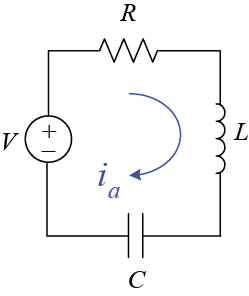

Since this circuit is a single loop, each node only has one input and one output; therefore, application of KCL simply shows that the current is the same throughout the circuit at any given time, $i(t)$. Now applying KVL around the loop and using the sign conventions indicated in the diagram, we arrive at the following **governing equation**.


$$
V(t) - R i - L \frac{di}{dt} - \frac{1}{C} \int i dt = 0
$$


We note that that the governing equation for the RLC circuit has an analogous form to the mass-spring-damper mechanical system. In particular, they are both second-order systems where the charge (integral of current) corresponds to displacement, the inductance corresponds to mass, the resistance corresponds to viscous damping, and the inverse capacitance corresponds to the spring stiffness. These analogies and others like them turn out to be quite useful conceptually in understanding the behavior of dynamical systems.

The state-space representation is found by choosing the charge on the capacitor and current through the circuit (inductor) as the state variables.


$$
\mathbf{x} = \left[ \begin{array}{c} q \\ i \end{array}\right]
$$


where,


$$
q = \int i dt
$$


The state equation is, therefore:


$$
\mathbf{\dot{x}} = \left[ \begin{array}{c} i \\ \frac{di}{dt} \end{array} \right] = \left[ \begin{array}{cc} 0 & 1 \\ -\frac{1}{LC} & -\frac{R}{L} \end{array} \right] \left[ \begin{array}{c} q \\ i \end{array} \right] + \left[ \begin{array}{c} 0 \\ \frac{1}{L} \end{array} \right] V(t)
$$


We choose the current as ouput as follows:


$$
y = \left[ \begin{array}{cc} 0 & 1 \end{array} \right] \left[ \begin{array}{c} q \\ i \end{array} \right]
$$


The transfer function representation may be found by taking the Laplace transform as we did for the mass-spring-damper or from the state-space equation as follows:


$$
\frac{I(s)}{V(s)} = C(s
\mathbf{I}-A)^{-1}B+D
= \left[ \begin{array}{cc} 0 & 1 \end{array} \right]
\left( s \left[ \begin{array}{cc} 1 & 0 \\ 0 & 1 \end{array} \right] - \left[
\begin{array}{cc} 0 & 1 \\ -\frac{1}{LC} & -\frac{R}{L} \end{array} \right] \right)^{-1} \left[ \begin{array}{c} 0 \\ \frac{1}{L} \end{array} \right]
$$



$$
\Rightarrow \ \frac{I(s)}{V(s)} = \frac{s}{Ls^2+Rs+\frac{1}{C}}
$$


The RLC state-space and transfer function models can be entered into MATLAB using the same procedure as discussed for the mass-spring-damper system above.

## System Identification

In this section, we have seen how to model systems using basic physical principles; however, often this is not possible either because the parameters of the system are uncertain, or the underlying processes are simply not understood. In these cases, we must rely on experimental measurements and statistical techniques to develop a system model, a process known as **system identification**. 

System identification may be performed using either time-domain or frequency-domain data, see the < ?aux=Extras_Identification Introduction: System Identification> page for further details. A couple of system identification activities can also be found from the **Hardware** tab located at the top of this window.

Also refer to MATLAB’s [System Identification Toolbox](http://www.mathworks.com/products/sysid/) for more information on this subject. 

## System Conversions

Most operations in MATLAB can be performed on either the transfer function, the state-space model, or the zero-pole-gain form. Furthermore, it is simple to transfer between these forms if the other representation is required. If you need to learn how to convert from one representation to another, see [http://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_Conversions](http://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_Conversions)  . 

# 2.    System Analysis

Once appropriate mathematical models of a system have been obtained, either in state-space or transfer function form, we may then analyze these models to predict how the system will respond in both the time and frequency domains. To put this in context, control systems are often designed to improve stability, speed of response, steady-state error, or prevent oscillations. In this section, we will show how to determine these dynamic properties from the system models.

Key MATLAB commands used in this tutorial are: [`tf`](http://www.mathworks.com/help/toolbox/control/ref/tf.html) ,  [`ssdata`](http://www.mathworks.com/help/toolbox/control/ref/ssdata.html) ,  [`pole`](http://www.mathworks.com/help/toolbox/control/ref/pole.html) ,  [`eig`](http://www.mathworks.com/help/techdoc/ref/eig.html) ,  [`step`](http://www.mathworks.com/help/toolbox/control/ref/step.html) ,  [`pzmap`](http://www.mathworks.com/help/toolbox/control/ref/pzmap.html) ,  [`bode`](http://www.mathworks.com/help/ident/ref/bode.html) ,  [`linearSystemAnalyzer`](http://www.mathworks.com/help/control/ref/linearsystemanalyzer-app.html)

## Time Response Overview

The **time response** represents how the state of a dynamic system changes in time when subjected to a particular input. Since the models we have derived consist of differential equations, some integration must be performed in order to determine the time response of the system. For some simple systems, a closed-form analytical solution may be available. However, for most systems, especially nonlinear systems or those subject to complicated inputs, this integration must be carried out numerically. Fortunately, MATLAB provides many useful resources for calculating time responses for many types of inputs, as we shall see in the following sections.

The time response of a linear dynamic system consists of the sum of the **transient response** which depends on the initial conditions and the  **steady-state response** which depends on the system input. These correspond to the homogenous (free or zero input) and the particular solutions of the governing differential equations, respectively.

## Frequency Response Overview

All the examples presented in this tutorial are modeled by linear constant coefficient differential equations and are thus linear time-invariant (LTI). LTI systems have the extremely important property that if the input to the system is sinusoidal, then the steady-state output will also be sinusoidal at the same frequency, but, in general, with different magnitude and phase. These magnitude and phase differences are a function of the frequency and comprise the **frequency response** of the system.

The frequency response of a system can be found from its transfer function in the following way: create a vector of frequencies (varying between zero or "DC" to infinity) and compute the value of the plant transfer function at those frequencies. If $G(s)$ is the open-loop transfer function of a system and $\omega$ is the frequency vector, we then plot $G(j\omega)$ versus $\omega$. Since $G(j\omega)$ is a complex number, we can plot both its magnitude and phase (the **Bode Plot**) or its position in the complex plane (the  **Nyquist Diagram**). Both methods display the same information, but in different ways.

## Stability

For our purposes, we will use the **Bounded Input Bounded Output (BIBO)** definition of stability which states that a system is stable if the output remains bounded for all bounded (finite) inputs. Practically, this means that the system will not "blow up" while in operation.

The transfer function representation is especially useful when analyzing system stability. If all poles of the transfer function (values of $s$ for which the denominator equals zero) have negative real parts, then the system is stable. If any pole has a positive real part, then the system is unstable. If we view the poles on the complex s-plane, then all poles must be in the left-half plane (LHP) to ensure stability. If any pair of poles is on the imaginary axis, then the system is marginally stable and the system will tend to oscillate. A system with purely imaginary poles is not considered BIBO stable. For such a system, there will exist finite inputs that lead to an unbounded response. The poles of an LTI system model can easily be found in MATLAB using the `pole` command, an example of which is shown below: 

s = tf('s');
G = 1/(s^2+2*s+5)

G =
 
        1
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.



pole(G)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i


Thus this system is stable since the real parts of the poles are both negative. The stability of a system may also be found from the state-space representation. In fact, the poles of the transfer function are the eigenvalues of the system matrix $A$. We can use the `eig` command to calculate the eigenvalues using either the LTI system model directly, `eig(G)`, or the system matrix as shown below.

[A,B,C,D] = ssdata(G);
eig(A)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i


## System Order

The order of a dynamic system is the order of the highest derivative of its governing differential equation. Equivalently, it is the highest power of $s$ in the denominator of its transfer function. The important properties of first-, second-, and higher-order systems will be reviewed in this section.

## First-Order Systems

First-order systems are the simplest dynamic systems to analyze. Some common examples include mass-damper systems and RC circuits.

The general form of the first-order differential equation is as follows


$$ 
\dot{y} + a y = b u \quad \textrm{or} \ \quad \tau \dot{y} + y = k_{dc} u
$$


The form of a first-order transfer function is


$$ 
G(s) = \frac{b}{s+a} = \frac{k_{dc}}{\tau s + 1}
$$


where the parameters $k_{dc}$ and $\tau$ completely define the character of the first-order system.

**DC Gain**

The DC gain, $k_{dc}$, is the ratio of the magnitude of the steady-state step response to the magnitude of the step input. For stable transfer functions, the **Final Value Theorem** demonstrates that the DC gain is the value of the transfer function evaluated at $s$ = 0. For first-order systems of the forms shown, the DC gain is $k_{dc} = b/a$. 

**Time Constant**

The time constant of a first-order system is $T_c = \tau = 1/a$ which is equal to the time it takes for the system's response to reach 63% of its steady-state value for a step input (from zero initial conditions) or to decrease to 37% of the initial value for a system's free response. More generally, it represents the time scale for which the dynamics of the system are significant. 

**Poles/Zeros**

First-order systems have a single real pole, in this case at $s = -a$. Therefore, the system is stable if $a$ is positive and unstable if $a$ is negative. Standard first-order system have no zeros. 

**Step Response**

We can calculate the system time response to a step input of magnitude $u$ using the following MATLAB commands:

k_dc = 5;
Tc = 10;
u = 2;

s = tf('s');
G = k_dc/(Tc*s+1)

G =
 
     5
  --------
  10 s + 1
 
Continuous-time transfer function.



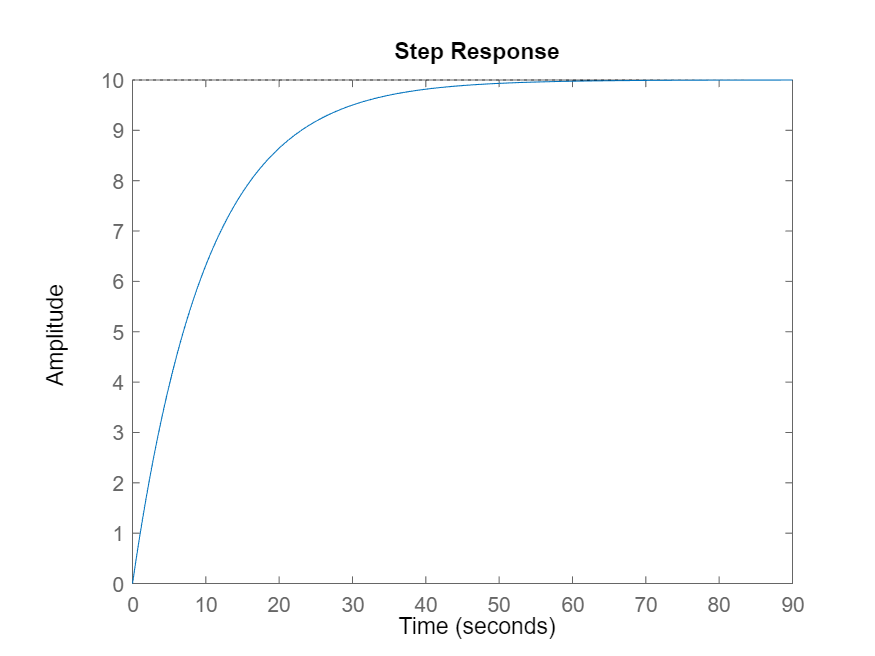


step(u*G)

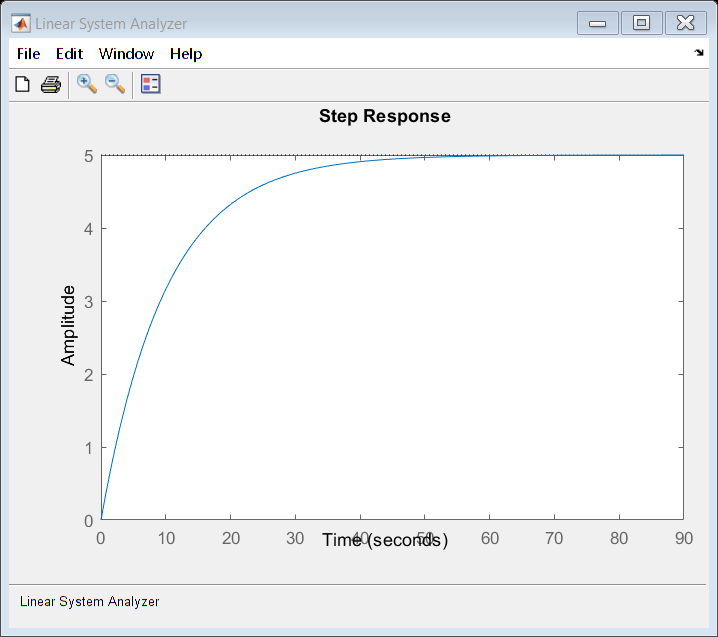

linearSystemAnalyzer("step", G)

Note: MATLAB also provides a powerful graphical user interface for analyzing LTI systems which can be accessed using the syntax `linearSystemAnalyzer('step',G)`.

If you right-click on the step response graph and select **Characteristics**, you can choose to have several system metrics overlaid on the response: peak response, settling time, rise time, and steady-state.

**Settling Time**

The settling time, $T_s$, is the time required for the system output to fall within a certain percentage (i.e. 2%) of the steady-state value for a step input. The settling times for a first-order system for the most common tolerances are provided in the table below. Note that the tighter the tolerance, the longer the system response takes to settle to within this band, as expected.

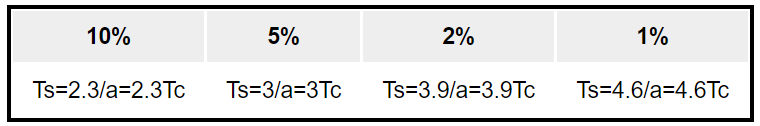

**Rise Time**

The rise time, $T_r$, is the time required for the system output to rise from some lower level x% to some higher level y% of the final steady-state value. For first-order systems, the typical range is 10% - 90%.

**Bode Plots**

Bode diagrams show the magnitude and phase of a system's frequency response, $G(j\omega)$, plotted with respect to frequency $\omega$. We can generate the Bode plot of a system $G$ in MATLAB using the syntax `bode(G)` as shown below. 

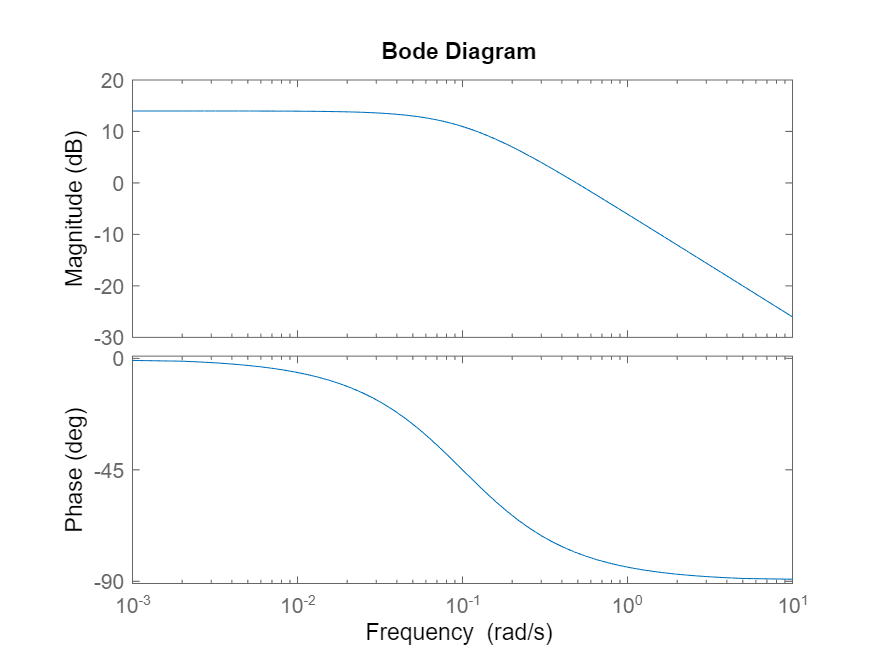

bode(G)

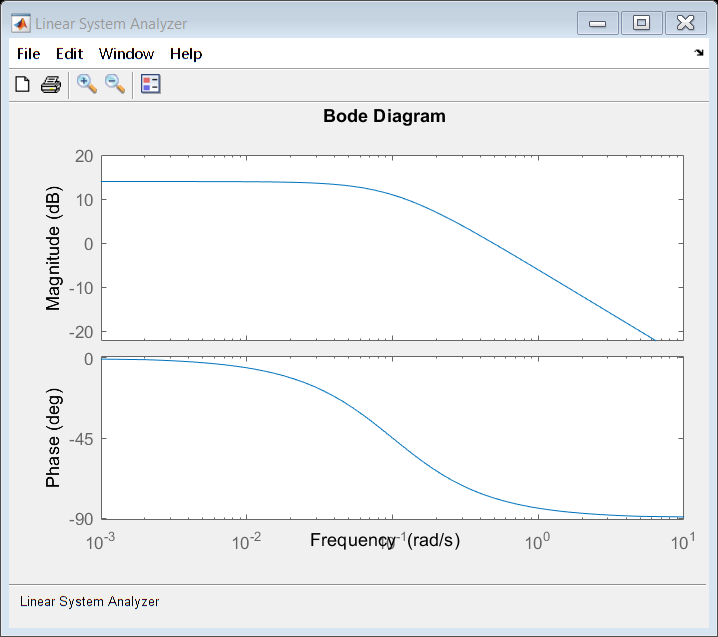

linearSystemAnalyzer('bode',G)

Again the same results could be obtained using the Linear System Analyzer GUI, `linearSystemAnalyzer('bode',G)`.

Bode plots employ a logarithmic frequency scale so that a larger range of frequencies are visible. Also, the magnitude is represented using the logarithmic **decibel unit (dB)** defined as:


$$
M_{dB} = 20 \log_{10} (M)
$$


As with the frequency axis, the decibel scale allows us to view a much larger range of magnitudes on a single plot. Also, as we shall see in subsequent tutorials, when components and controllers are placed in series, the transfer function of the overall system is the product of the individual transfer functions. Using the dB scale, the magnitude plot of the overall system is simply the sum of the magnitude plots of the individual transfer functions. The phase plot of the overall system is also just the sum of the individual phase plots.

The low frequency magnitude of the first-order Bode plot is $20\log(k_{dc})$. The magnitude plot has a bend at the frequency equal to the absolute value of the pole (ie. $\omega = a$), and then decreases 20 dB for every factor of ten increase in frequency (slope = -20 dB/decade). The phase plot is asymptotic to 0 degrees at low frequencies, and asymptotic to -90 degrees at high frequencies. Between frequency 0.1a and 10a, the phase changes by approximately -45 degrees for every factor of ten increase in frequency (-45 degrees/decade).

We will see in the Frequency Methods for Controller Design Section how to use Bode plots to calculate closed-loop stability and performance of feedback systems.

## Second-Order Systems

Second-order systems are commonly encountered in practice, and are the simplest type of dynamic system to exhibit oscillations. Examples include mass-spring-damper systems and RLC circuits. In fact, many true higher-order systems may be approximated as second-order in order to facilitate analysis. 

The canonical form of the second-order differential equation is as follows


$$ 
m \ddot{y} + b \dot{y} + k y = f(t) \quad \textrm{or} \ \quad \ddot{y} + 2\zeta\omega_n \dot{y} + \omega_n^2 y = k_{dc} \omega_n^2 u
$$


The canonical second-order transfer function has the following form, in which it has two poles and no zeros.


$$ 
G(s) = \frac{1}{ms^2+bs+k} = \frac{k_{dc} \omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}
$$


The parameters $k_{dc}$, $\zeta$, and $\omega_n$ characterize the behavior of a canonical second-order system.

**DC Gain**

The DC gain, $k_{dc}$, again is the ratio of the magnitude of the steady-state step response to the magnitude of the step input, and for stable systems it is the value of the transfer function when $s = 0$. For the forms given,


$$
k_{dc} = \frac{1}{k}
$$


**Damping Ratio**

The damping ratio $\zeta$ is a dimensionless quantity charaterizing the rate at which an oscillation in the system's response decays due to effects such as viscous friction or electrical resistance. From the above definitions, 


$$
\zeta = \frac{b}{2 \sqrt{k m}}
$$


**Natural Frequency**

The natural frequency $\omega_n$ is the frequency (in rad/s) that the system will oscillate at when there is no damping, $\zeta = 0$. 


$$
\omega_n = \sqrt{\frac{k}{m}}
$$


**Poles/Zeros**

The canonical second-order transfer function has two poles at:


$$
s_p = -\zeta \omega_n \pm j \omega_n \sqrt{1-\zeta^2}
$$


**Underdamped Systems**

If $\zeta < 1$, then the system is **underdamped**. In this case, both poles are complex-valued with negative real parts; therefore, the system is stable but oscillates while approaching the steady-state value. Specifically, the natural response oscillates with the damped natural frequency, $\omega_d = \omega_n \sqrt{1-\zeta^2}$ (in rad/sec).

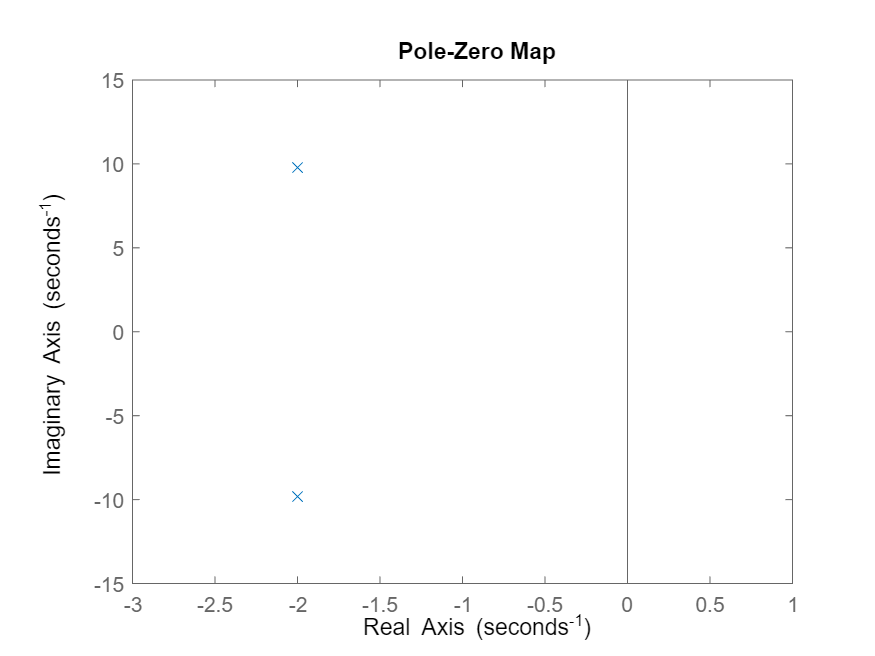

k_dc = 1;
w_n = 10;
zeta = 0.2;

s = tf('s');
G1 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

pzmap(G1)
axis([-3 1 -15 15])

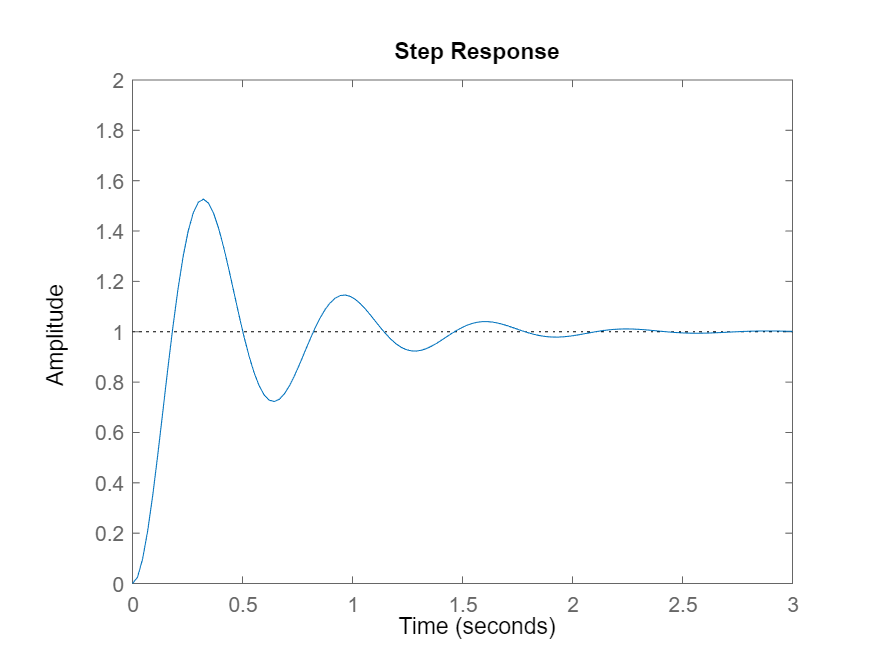

step(G1)
axis([0 3 0 2])

**Settling Time**

The settling time, $T_s$, is the time required for the system ouput to fall within a certain percentage of the steady-state value for a step input. For a canonical second-order, underdamped system, the settling time can be approximated by the following equation: 


$$
T_s = \frac{- \ln(\mathrm{tolerance}\;\mathrm{fraction})}{\zeta \omega_n}
$$


The settling times for the most common tolerances are presented in the following table:

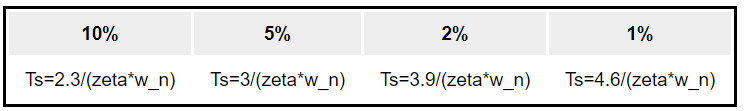

**Percent Overshoot**

The percent overshoot is the percent by which a system's step response exceeds its final steady-state value. For a second-order underdamped system, the percent overshoot $Mp$ is directly related to the damping ratio by the following equation. Here, $Mp$ is a decimal number where 1 corresponds to 100% overshoot.


$$
Mp = e^{\left( \frac{-\zeta\pi}{\sqrt{1-\zeta^2}} \right)}
$$


For second-order underdamped systems, the 1% settling time, $T_s$, 10-90% rise time, $T_r$, and percent overshoot, $Mp$, are related to the damping ratio and natural frequency as shown below.


$$
T_s \approx \frac{4.6}{\zeta \omega_n}
$$



$$
T_r \approx \frac{1.8}{\omega_n}
$$



$$
\zeta = \frac{-\ln(Mp)}{\sqrt{\pi^2+\ln^2(Mp)}}
$$


**Overdamped Systems**

If $\zeta > 1$, then the system is **overdamped**. Both poles are real and negative; therefore, the system is stable and does not oscillate. The step response and a pole-zero map of an overdamped system are calculated below:

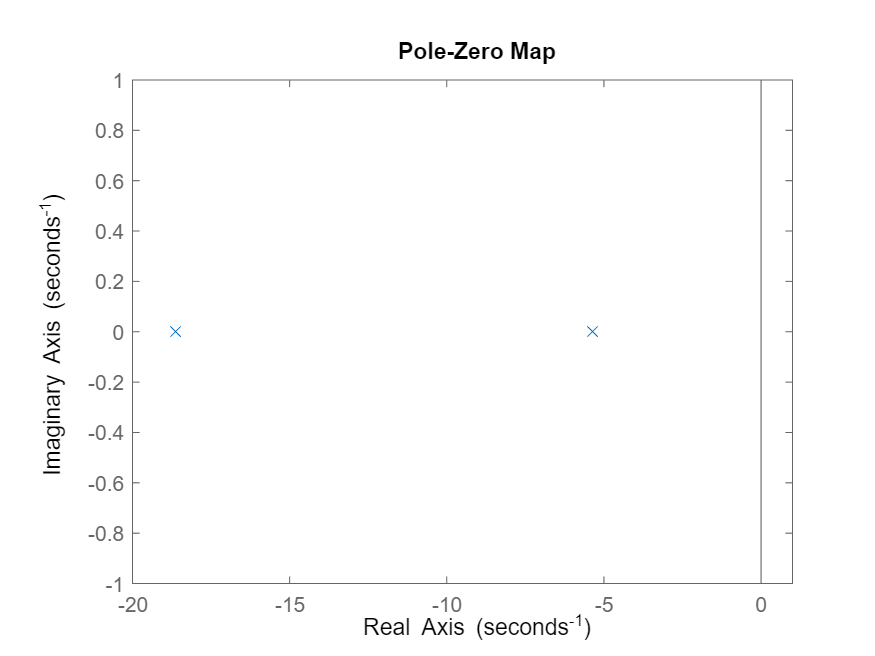

zeta = 1.2;

G2 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

pzmap(G2)
axis([-20 1 -1 1])

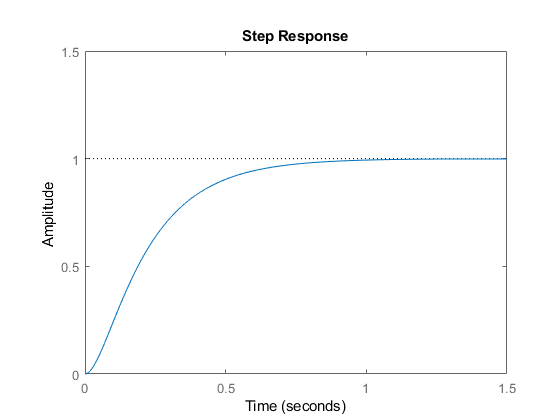

step(G2)
axis([0 1.5 0 1.5])

**Critically-Damped Systems**

If $\zeta = 1$, then the system is **critically damped**. Both poles are real and have the same magnitude, $s_p = -\zeta\omega_n$. For a canonical second-order system, the quickest settling time is achieved when the system is critically damped. Now change the value of the damping ratio to 1, and re-plot the step response and pole-zero map.

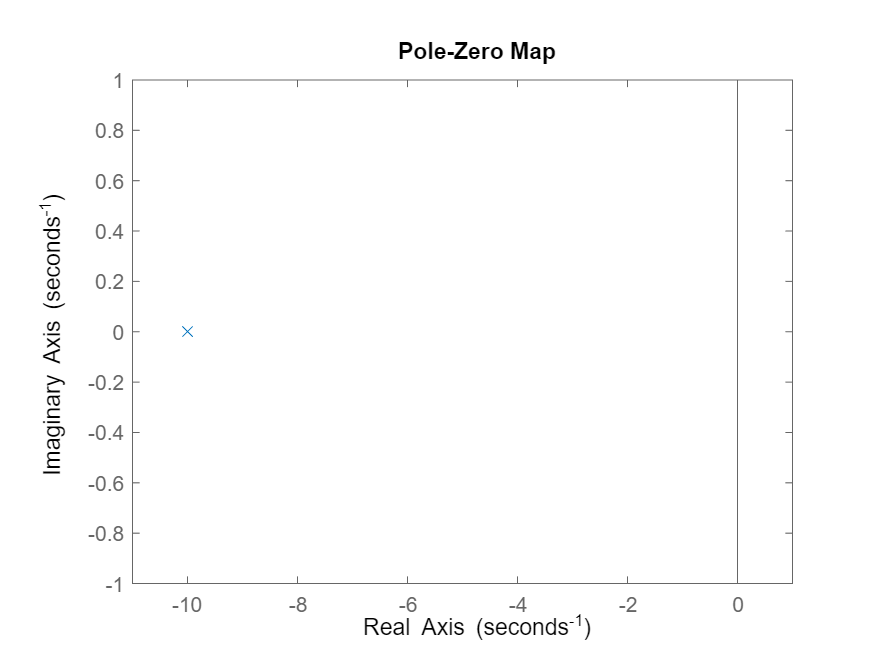

zeta = 1;

G3 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

pzmap(G3)
axis([-11 1 -1 1])

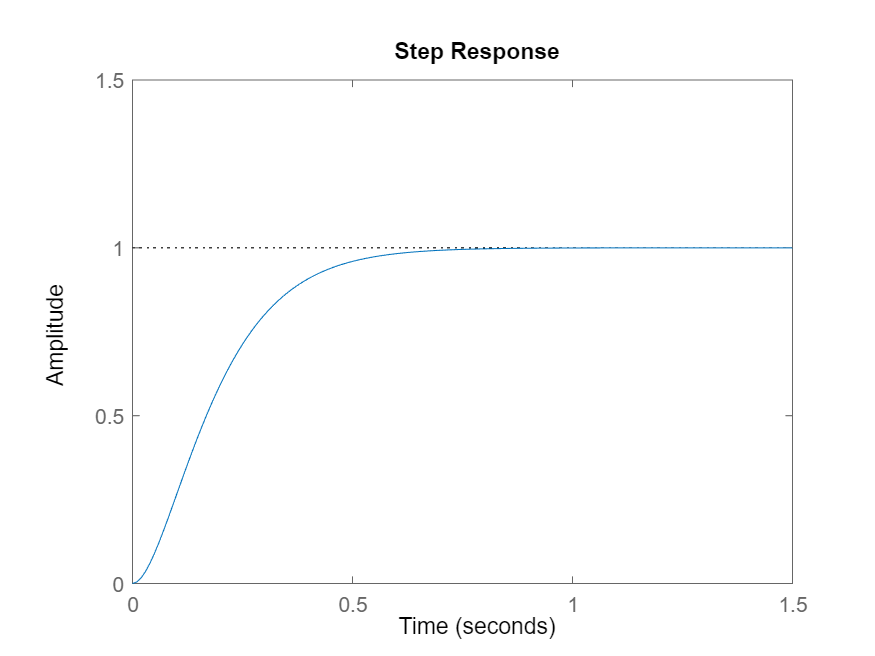

step(G3)
axis([0 1.5 0 1.5])

**Undamped Systems**

If $\zeta = 0$, then the system is **undamped**. In this case, the poles are purely imaginary; therefore, the system is marginally stable and the step response oscillates indefinitely. 

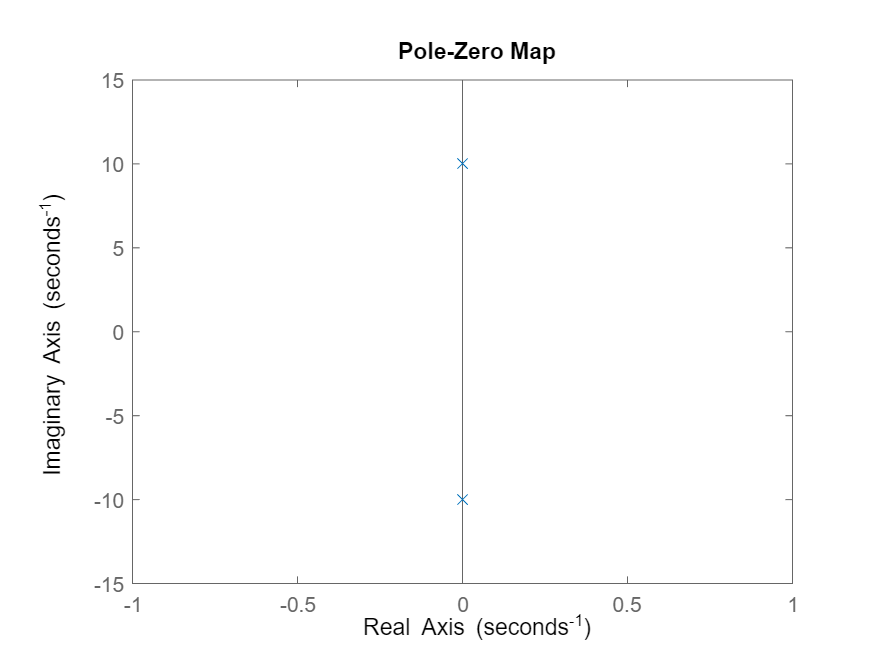

zeta = 0;

G4 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

pzmap(G4)
axis([-1 1 -15 15])

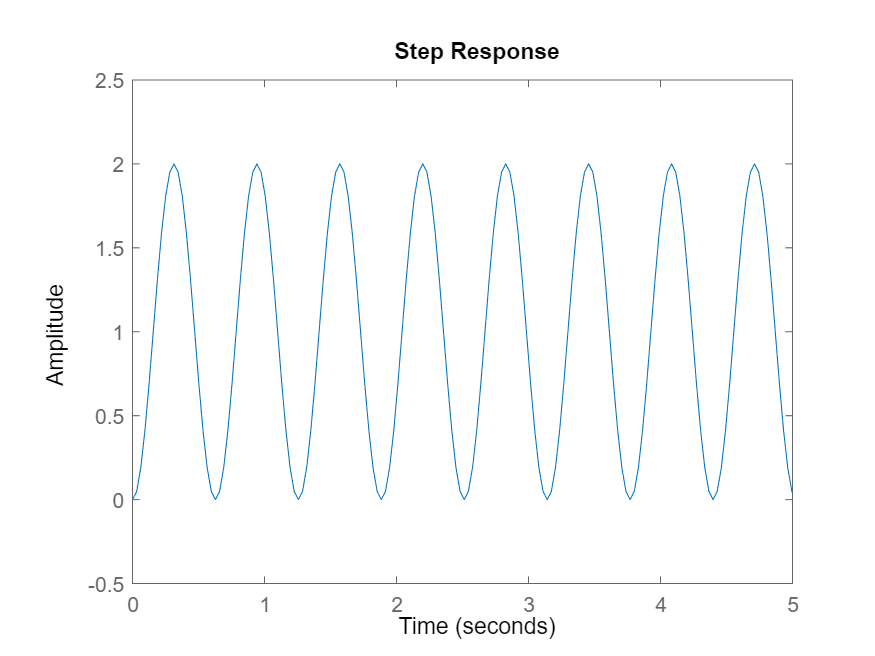

step(G4)
axis([0 5 -0.5 2.5])

**Bode Plot**

We show the Bode magnitude and phase plots for all damping conditions of a second-order system below:

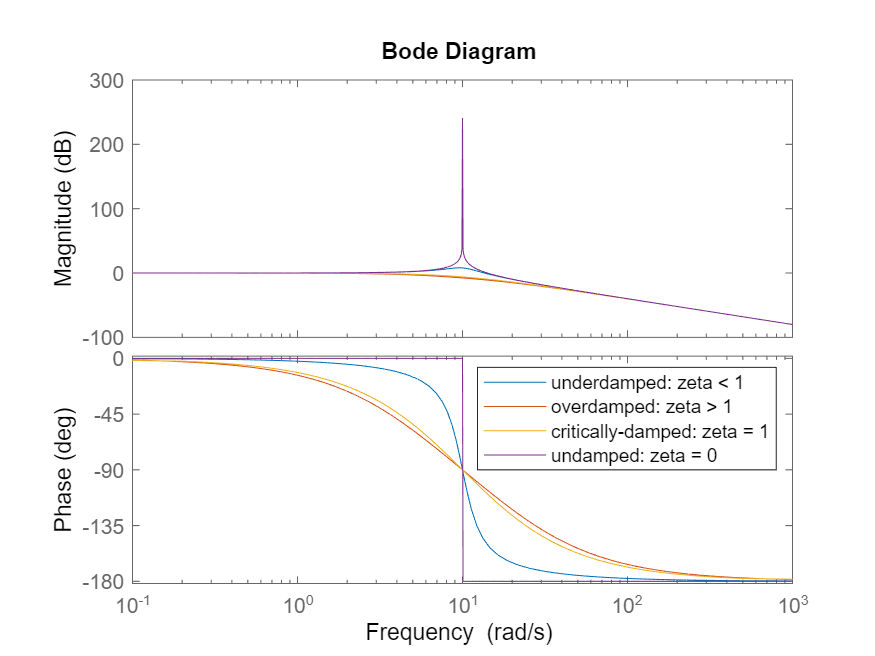

bode(G1,G2,G3,G4)
legend('underdamped: zeta < 1','overdamped: zeta > 1','critically-damped: zeta = 1','undamped: zeta = 0')

The magnitude of the bode plot of a second-order system drops off at -40 dB per decade in the limit, while the relative phase changes from 0 to -180 degrees. For underdamped systems, we also see a resonant peak near the natural frequency, $\omega_n$ = 10 rad/s. The size and sharpness of the peak depends on the damping in the system, and is charaterized by the quality factor, or **Q-Factor**, defined below. The Q-factor is an important property in signal processing.


$$
Q = \frac{1}{2\zeta}
$$
